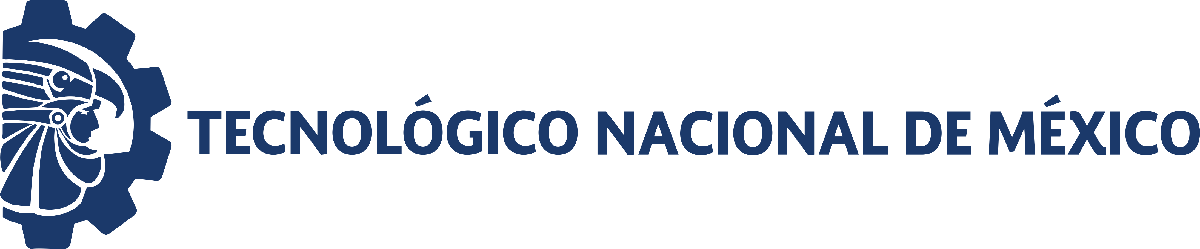                                 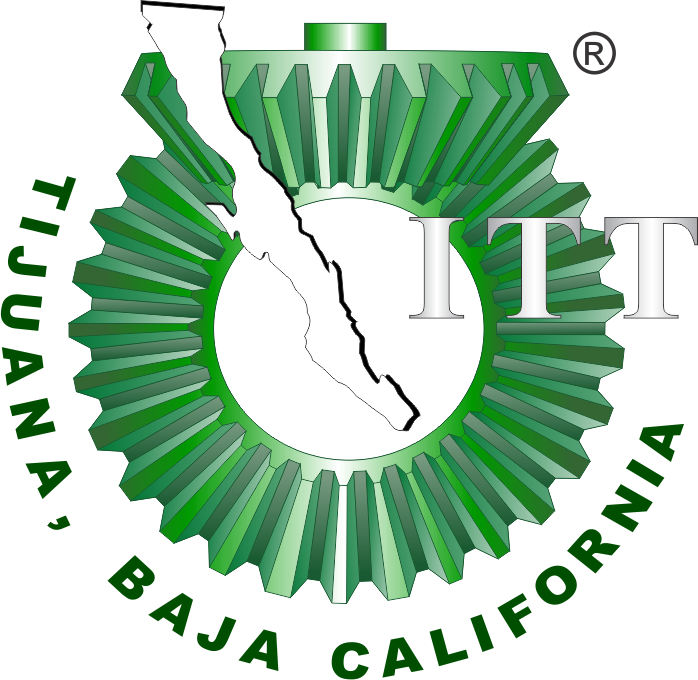

# Práctica uno: Diseño de controladores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

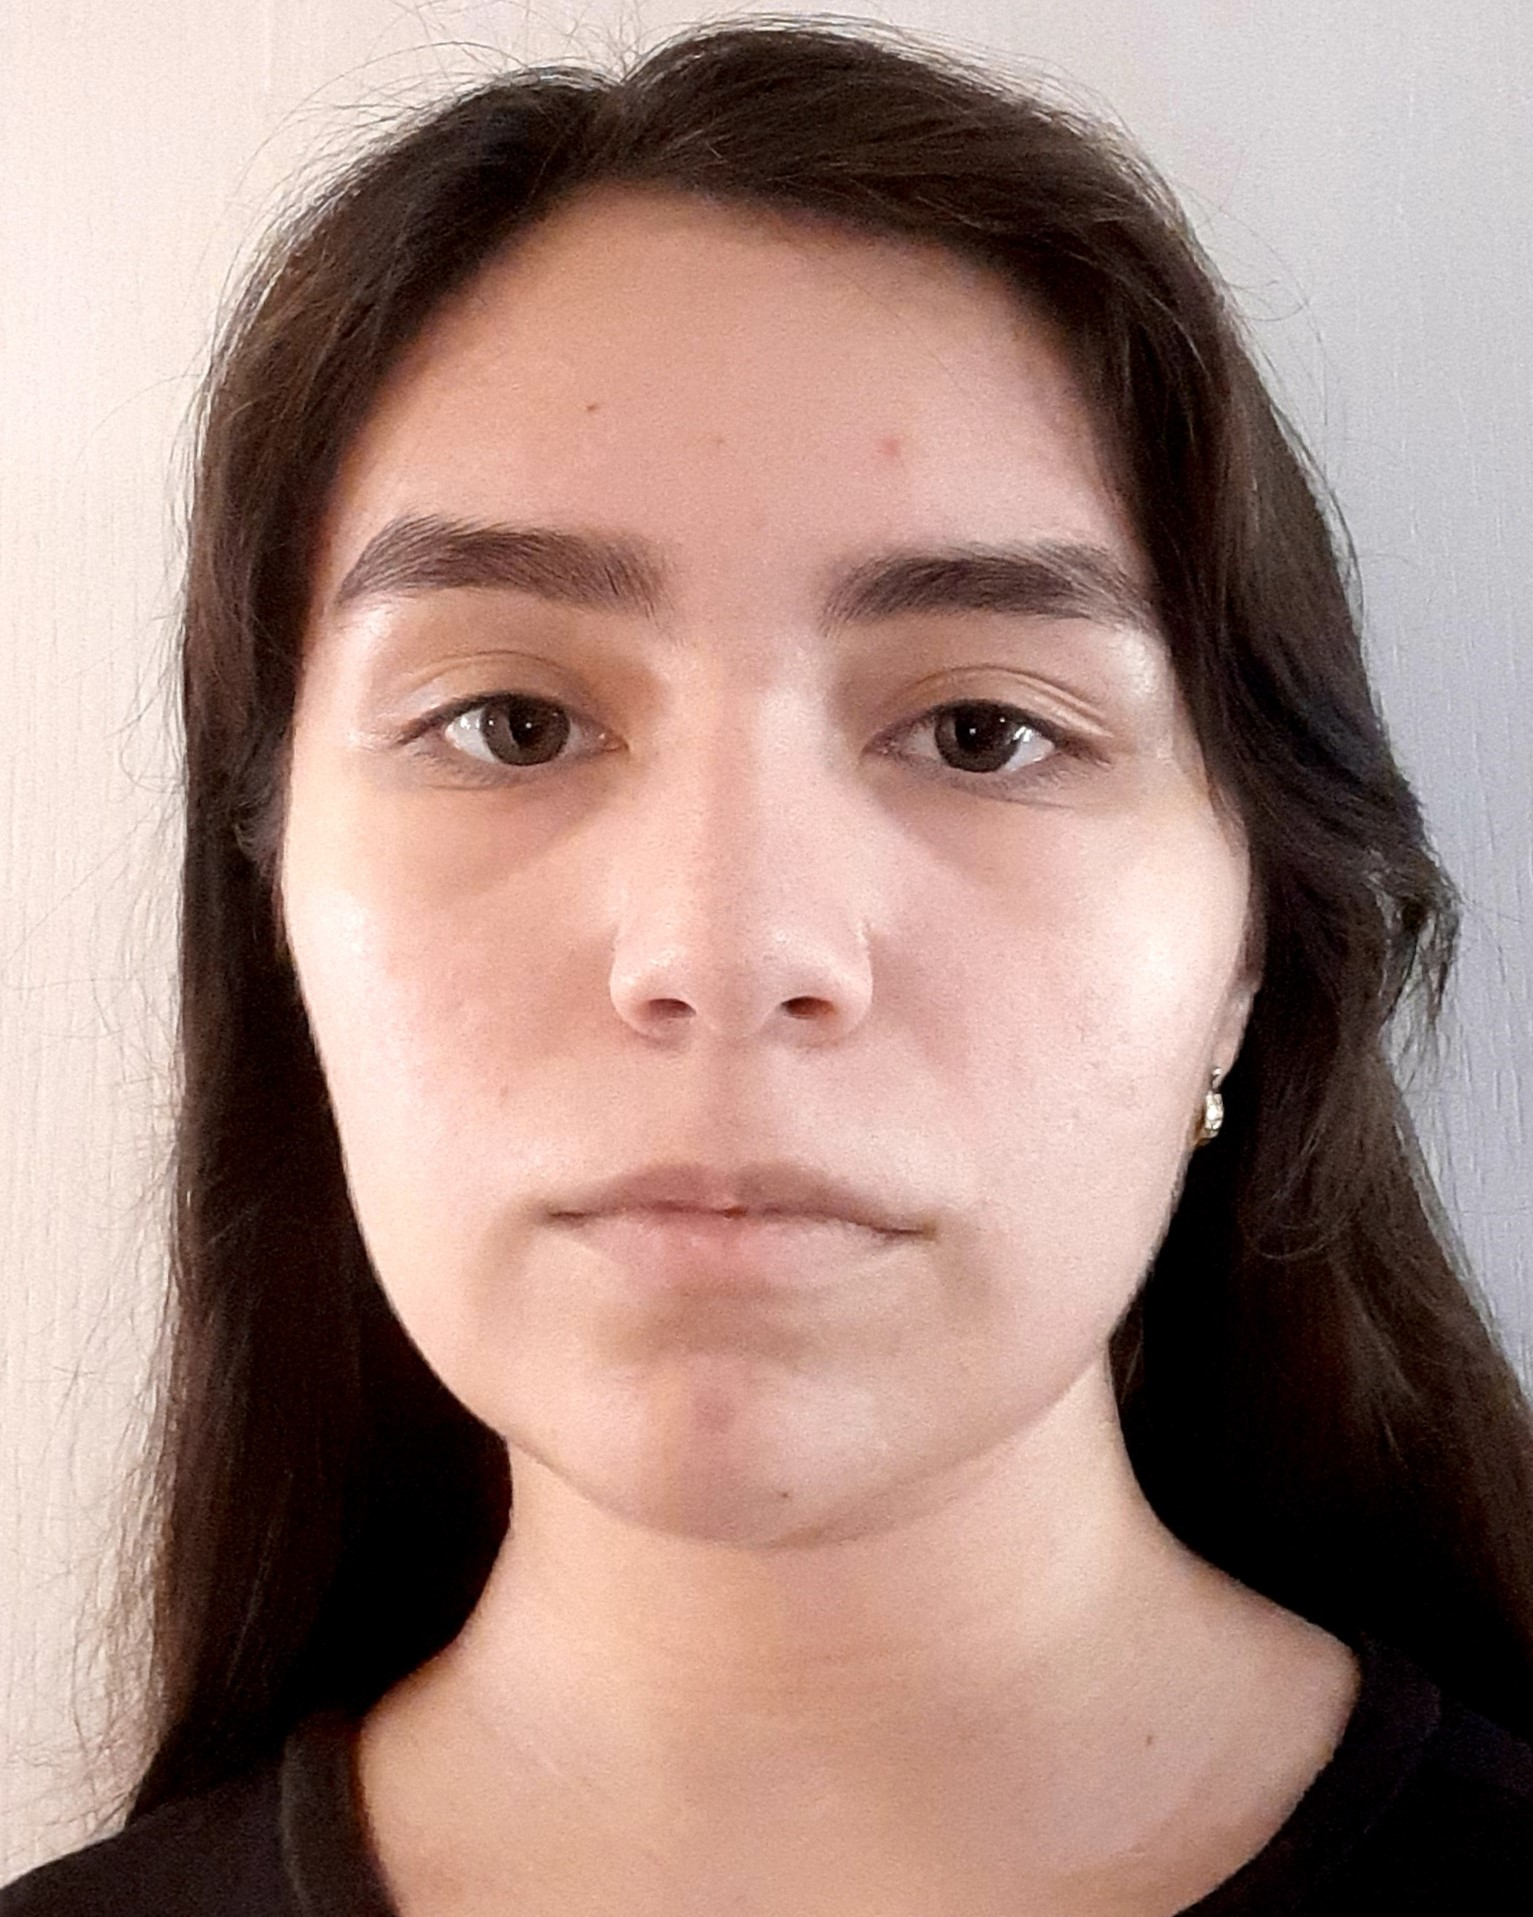

Nombre del alumno: Villa Camacho Abigail

Número de control: 22212276

Correo institucional: L22212276**@tectijuana.edu..mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema_circuito1';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta al escalón

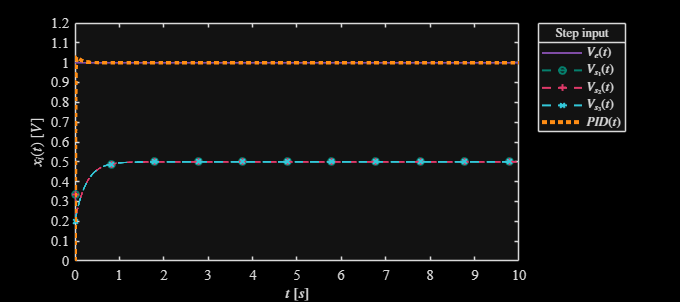

Signal = 'Step';
set_param('sistema_circuito1/S1','sw','1');
set_param('sistema_circuito1/Ve(t)','sw','1');
set_param('sistema_circuito1/Vs1(t)', 'VectorFormat', '1-D Array');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs1,x1.Vs2,x1.Vs3,x1.PID,Signal);

## Respuesta al impulso

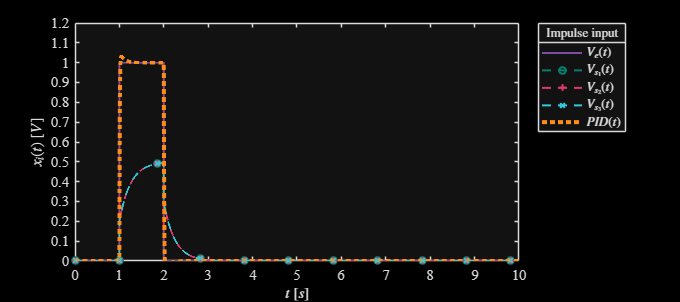

Signal = 'Impulse';
set_param('sistema_circuito1/S1','sw','0');
set_param('sistema_circuito1/Ve(t)','sw','1');
x2 = sim(file,parameters);
plotsignals (x2.t,x2.Ve,x2.Vs1,x2.Vs2,x2.Vs3,x2.PID,Signal)

## Respuesta a la rampa

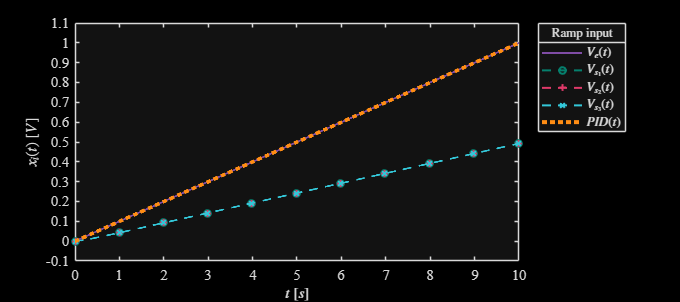

Signal = 'Ramp';
set_param('sistema_circuito1/S2','sw','1');
set_param('sistema_circuito1/Ve(t)','sw','0');
x3 = sim(file,parameters);
plotsignals (x3.t,x3.Ve,x3.Vs1,x3.Vs2,x3.Vs3,x3.PID,Signal)

## Respuesta a la función sinusoidal

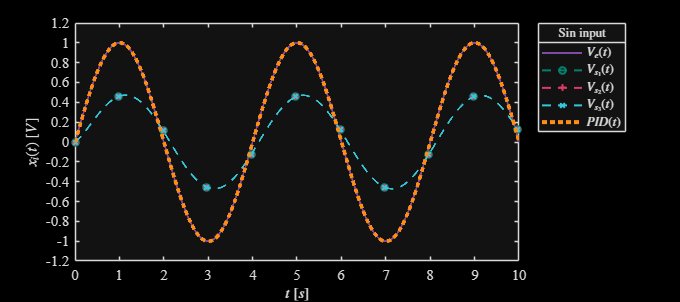

Signal = 'Sin';
set_param('sistema_circuito1/S2','sw','0');
set_param('sistema_circuito1/Ve(t)','sw','0');
x4 = sim(file,parameters);
plotsignals (x4.t,x4.Ve,x4.Vs1,x4.Vs2,x4.Vs3,x4.PID,Signal)

## Función: Respuesta a las señales

function plotsignals (t,Ve,Vs1,Vs2,Vs3,PID,Signal)
set(figure(),'Color','k')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [0.4980,0.2980,0.6471;
            0.0196,0.4980,0.4275;
            0.8745,0.2235,0.4118;
            0.2000,0.7804,0.8471;
            1.0000,0.5529,0.0784;
            0.4824,0.1765,0.2627];
colororder(mycolors)

p = plot(t, Ve, '-', t, Vs1, '--o', t, Vs2, '--+', t, Vs3, '--x', t,...
PID, ':','LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
set(p(5), 'LineWidth', 3);
L = legend('$V_e(t)$', '$V_{s_1}(t)$','$V_{s_2}(t)$','$V_{s_3}(t)$','$PID(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
title(L,[Signal, ' input'], 'FontSize', 10);

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11 )

    xlim([0,10]); xticks(0:1:10);
    if Signal == "Step" || Signal == "Impulse"
        ylim([0,1.2]); yticks(0:0.1:1.2);
    elseif Signal == "Ramp"
        ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1);
    elseif Signal == "Sin"
        ylim([-1.2 1.2]); yticks(-1.2:0.2:2);
    end

    exportgraphics(gcf,[Signal, '.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal, '.png'],'ContentType','vector')

end